% 

change p, with fixed s

% 

n = 200; % number of datapoints
p = 100;
s_vec = [2, 4, 6]


%s = 2;


s_vec =      2     4     6


sigma = 1;
K=2

K = 2

n_bar = n/K;
C_1 = 10;
beta = 1/(1+sqrt(log(n)/(C_1*n)));
C_2 = 1;
C_3 = 1;
delta = 0.9 * beta^2/(1-beta)^2 * C_2/K;
m = 4 * (1+delta)^2/delta^2;


R_n = 7.4948e-07

mu_1 = [];
mu_2 = [];
separation_vec =[];
rounding = 1e-4;
cluster_true = 1:n/2

cluster_true =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


clustering_acc = repelem(0,length(s_vec))

clustering_acc =      0     0     0


1:n/2

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


observe some pattern

when the performance becomes not so good

for i = 1:length(s_vec)
    s = s_vec(i);
    R_n = (1-beta)^2/(1+delta)/log(n)*( ...
    sqrt(s * log(n)) / n_bar + log(n)/n_bar ...
    )
    a =  sqrt(1+ (1-beta)^2/(1+delta) * s / (m*log(n)) + C_3*R_n)
    separation_vec(i) = sqrt( ...
    sqrt( 4 * sigma^2 * (1+2*delta) / (1-beta)^2 * sqrt(1+a) * log(n) ) );


    %data generation
    mu_1 =  -separation_vec(i) * [repelem(1,s), repelem(0,p-s)]
    mu_2 = separation_vec(i) * [repelem(1,s), repelem(0,p-s)]

    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);

    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);


% original affinity matrix (or similarity matrix)
%scale

    A = (x * x') / n;
    
    

% solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded = Z_org>rounding;
    cluster_est = find(rounded(:,1));
    clustering_acc(i) = mean(cluster_true' == cluster_est);
   %thresholded affinity matrix
  %  thres = 0;
  %  A_thres = A.*(abs(A)>thres);
   % Z_thres = kmeans_sdp(A_thres, 2);

end

R_n = 2.2640e-07

a = 1.0000

mu_1 =   -45.4362  -45.4362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mu_2 =    45.4362   45.4362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =    21.0635   20.3431   20.8709   20.4942   20.9015   20.5049   20.3783   20.1826   21.1697   20.6109   20.3365   20.4243   20.8093   20.5615   20.7002   20.5693   20.0708   20.8402   20.4655   20.5367   20.9855   20.7541   20.2882   20.5167   20.3742   20.5537   20.2812   20.3587   21.0040   21.3488   20.6249   20.4717   20.3871   20.6054   19.9342   20.3317   20.6747   20.4377   20.8898   20.4764   20.7885   21.1075   20.6811   20.4457   20.6215   20.3381   20.6559   20.4954   20.4022   20.6378
   20.3431   20.6742   20.6706   20.1200   20.6718   20.2792   20.1505   20.0941   20.8071   20.2149   20.0668   20.2499   20.5261   20.2928   20.3379   20.3774   19.8300   20.4848   20.2376   20.2320   20.6780   20.4278   20.0575   20.2486   20.2149   20.2928   20.1542   20.0781   20.7797   21.0007   20.3521   20.2982   20.0686   20.3364   19.8038   20.0736   20.3742   20.0780   20.7350   20.2600   20.5855   20.9036   20.3542   20.1587   20.2198   20.0613   20.3459   20.1429   20.0936   20

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

R_n = 2.6209e-07

a = 1.0000

mu_1 =   -45.4362  -45.4362  -45.4362  -45.4362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mu_2 =    45.4362   45.4362   45.4362   45.4362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =    41.4792   41.6516   40.8091   40.8572   40.8037   41.5925   40.9213   41.1465   40.4904   41.4642   41.0030   40.7157   42.1258   40.9713   40.9691   40.4325   41.1200   40.8818   41.6319   41.3742   41.5738   40.9788   41.8866   40.9602   41.2957   40.5921   41.3443   41.0061   41.6180   41.1152   41.8411   40.2686   41.0581   40.9143   40.4728   41.1367   41.7700   40.7582   41.5644   41.4142   41.4678   41.7954   41.3722   41.3214   40.2056   41.3371   41.6151   41.3509   41.3484   40.9756
   41.6516   42.7565   41.2570   41.4649   41.4146   42.2465   41.6900   41.8501   41.1601   42.0612   41.6615   41.4554   42.7961   41.5851   41.6860   41.0122   41.8253   41.5659   42.2568   42.0428   42.3602   41.6398   42.4380   41.5400   41.9187   41.2807   41.9969   41.7010   42.2267   41.7806   42.4653   40.7598   41.7487   41.6212   41.1594   41.8627   42.4314   41.3525   42.2663   42.0905   41.9827   42.4992   42.0042   41.9752   40.8965   42.0294   42.2721   42.0211   41.9628   41

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

R_n = 2.8947e-07

a = 1.0000

mu_1 =   -45.4363  -45.4363  -45.4363  -45.4363  -45.4363  -45.4363         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mu_2 =    45.4363   45.4363   45.4363   45.4363   45.4363   45.4363         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =    62.3023   61.7953   60.1976   62.0825   61.7747   61.5431   61.6971   61.7281   61.6332   61.3816   61.2722   61.7308   61.4435   62.5673   62.2909   62.0073   61.5975   61.7204   61.6473   62.5820   61.6415   61.7391   61.6649   61.1937   62.2350   61.1759   62.4816   61.7406   60.9609   62.2213   61.5121   62.0107   62.1130   61.3444   61.9072   61.1826   62.0360   61.4848   62.0630   61.3111   62.4838   61.0080   60.9030   62.2444   62.3044   62.1996   61.2600   60.9096   61.4449   61.5682
   61.7953   62.3896   60.2506   62.2135   61.8901   61.5861   61.8364   61.8551   61.6575   61.4636   61.3393   61.9639   61.4413   62.6438   62.4173   62.2590   61.7455   61.7163   61.7380   62.6435   61.7047   61.8036   61.8036   61.3594   62.3493   61.3314   62.5716   61.8918   61.0067   62.3777   61.4992   62.2835   62.3320   61.5845   62.0856   61.2557   62.0971   61.5941   62.1525   61.5530   62.5750   61.0868   61.0359   62.4165   62.4373   62.2251   61.4089   61.0644   61.6140   61

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06


clustering_acc

clustering_acc =      1     1     1


a = 1.0000

% disadvangage of their bound. dependence on p is p 
%a = 0.1;


mu_1 =   -45.4362  -45.4362         0         0         0         0         0         0         0         0


mu_2 =    45.4362   45.4362         0         0         0         0         0         0         0         0


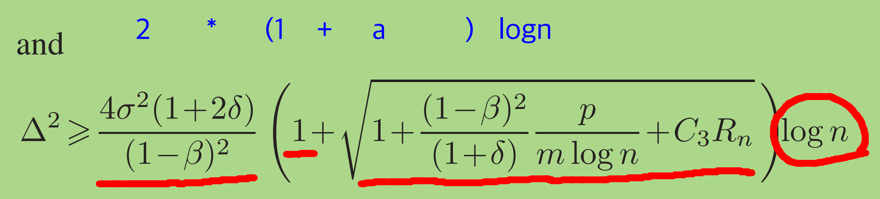\

**how to determine a?**

\

(p=1 i.e. univariate gaussian)

### Original method vs thresholding

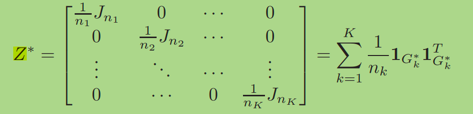

A =    20.2874   20.2980   20.4285   20.4702   19.4013   20.8367   20.2299   19.9411   20.2810   20.6136   20.3596   20.8405   20.4206   20.1139   20.2824   20.7341   20.6394   20.2838   20.7089   20.0325   21.2540   20.1800   20.6597   20.1835   20.1331   21.1927   20.0354   20.9295   21.2046   20.3608   20.3059   20.4310   21.3180   20.0476   20.6977   20.1218   20.3876   20.2708   19.8016   19.9234   20.8896   20.6627   21.1059   20.5182   20.5579   19.8970   20.5678   20.2358   20.2384   20.0546
   20.2980   20.4027   20.4809   20.5475   19.4922   20.8947   20.2664   19.9924   20.3319   20.6399   20.4199   20.8819   20.4934   20.1579   20.3061   20.7710   20.6768   20.2846   20.7664   20.0545   21.3120   20.2024   20.7028   20.2545   20.1845   21.2424   20.1227   20.9553   21.2384   20.3892   20.3315   20.4957   21.3557   20.0845   20.7606   20.1115   20.4519   20.3007   19.8793   20.0064   20.9351   20.6982   21.0969   20.5886   20.5937   19.9548   20.5685   20.2781   20.3327   20

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

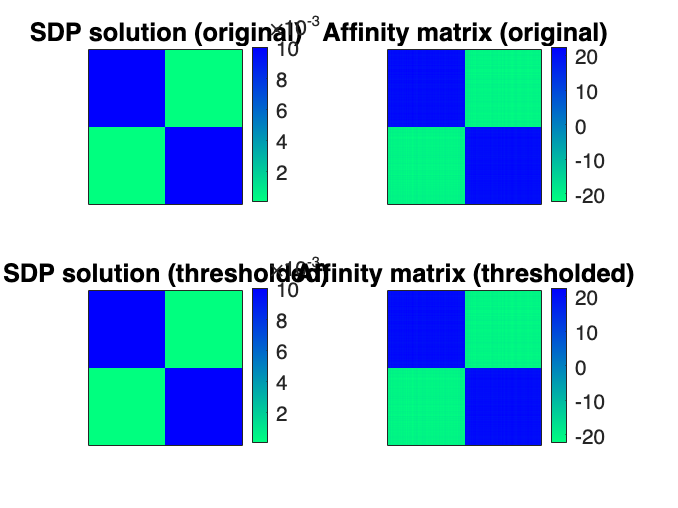


% takes about 15 seconds on this laptop


figure;

subplot(2,2,1)
imagesc(Z_org)
title('SDP solution (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,2)
imagesc(A)
title('Affinity matrix (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,3)
imagesc(Z_thres)
title('SDP solution (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,4)
%imagesc(abs(A))
imagesc(A_thres)
title('Affinity matrix (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)


min(A.*(abs(A)>thres))

ans =    -7.3146         0  -15.4388  -13.2934  -10.6362   -8.0561         0   -9.9084         0         0         0   -7.9760  -11.6088  -15.4308   -7.8437         0   -9.9206  -11.0710   -9.9950  -13.6472  -10.8495   -9.4021   -8.3519   -8.8600         0   -8.0577         0   -7.1181         0  -11.9161         0   -9.7707         0         0  -18.6968  -14.7153  -15.2436         0         0  -10.0792         0         0  -13.4388         0  -12.0495         0   -8.7153         0  -10.5346         0
